# Battery testing, modelling, and state estimation - Offline State-of-Health Estimation and Diagnostics

*Vaclav Knap*

In this task, you shall analyze the degradation of a lithium-ion cell.

The measured cell has a composition NMC/Si-G, cylindrical 18650 format and a nameplate capacity 3 Ah (practical 2.75 Ah). It was aged by cycling with a 10% cycle depth. Three measurements correspond to:

0 cycles = 2.7583 Ah

12000 cycles = 2.5447 Ah

24000 cycles = 2.4496 Ah

The electrochemical impedance spectroscopy (EIS) measurements are done at 60% SOC.

The reference performance tests (RPTs) contain constant-current charging step that you will use for the incremental capacity analysis.

Your task is:

1) Analyze degradation using EIS technique

    a. Fit an electrical circuit model to EIS data.

    b. Apply the relations on page 16, Lecture 10, in order to quantify the degradation modes.

    c. Provide a discussion related to the evolution of EIS battery parameters and degradation modes.

2) Analyze degradation using incremental capacity (IC) and differential voltage (DV) techniques

    a. Process the measured data to obtain IC and DV curves.

    b. Apply relations on page 12, Lecture 10, in order to quantify the degradation modes.

    c. Provide a discussion related to the evolution of IC/DV peaks and degradation modes.

list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end
set(0, 'DefaultAxesFontSize', 16);
set(0, 'DefaultTextFontSize', 16);

%% Load the EIS data and plot them for an overview
close all
clear

eis_cyc0 = readtable('eis_0cyc.csv');

eis_cyc12000 = readtable('eis_12000cyc.csv');

eis_cyc24000 = readtable('eis_24000cyc.csv');

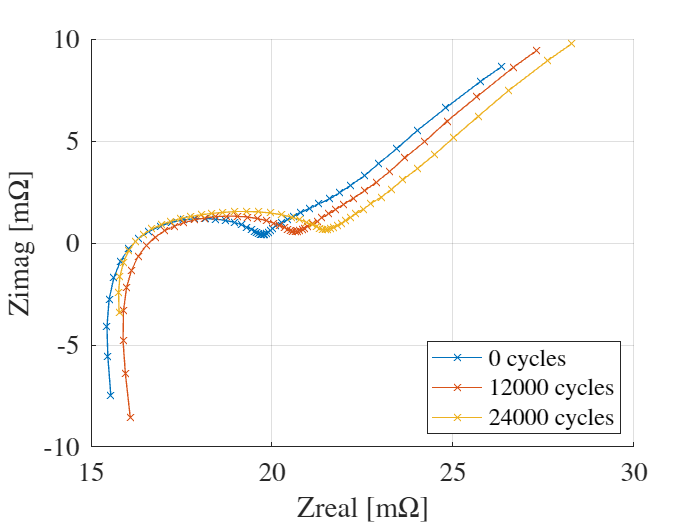

eis_cyc0 = eis_cyc0(2:end,:);

figure
hold all
plot(eis_cyc0.Zreal1,-eis_cyc0.Zimg1,'x-')
plot(eis_cyc12000.Zreal1,-eis_cyc12000.Zimg1,'x-')
plot(eis_cyc24000.Zreal1,-eis_cyc24000.Zimg1,'x-')
xlabel('Zreal [m$\Omega$]')
ylabel('Zimag [m$\Omega$]')
grid on
legend('0 cycles','12000 cycles','24000 cycles','Location','southeast')



% The impedance data are in mOhms, need to transfer them into Ohms. The
% measured frequency will be needed as well:
zr0 = eis_cyc0.Zreal1/1000;
zi0 = eis_cyc0.Zimg1/1000;
f0 = eis_cyc0.ActFreq;

% finish for 12000 cycles
% finish for 24000 cycles


## Fitting EIS for Cyc0

% Task 1) a.
inputvariablevertcat = vertcat (f0,f0);
inputdatavertcat = vertcat(zr0,zi0);

% You need to edit number of elements based on your circuit
startPar = [0.01, 0.01, 100, 0.5];   %initial guess, try to read out from the graphs
LB = [0, 0, 0, 0];                        %lower boundaries
UB = [1, 1, 10000, 1];                    %upper boundaries

[fitPar,resnorm2,residual2,exitflag2,output2] = lsqcurvefit(@parestimation,startPar,inputvariablevertcat,inputdatavertcat,LB,UB) 


Local minimum possible.

lsqcurvefit stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


fitPar = 1.0e+03 *

    0.0000    0.0000    9.6959    0.0006


resnorm2 = 2.3752e-04

residual2 =     0.0028
    0.0029
    0.0029
    0.0029
    0.0028
    0.0026
    0.0023
    0.0021
    0.0018
    0.0015


exitflag2 = 3

output2 = struct with fields:
      firstorderopt: 3.3046e-04
         iterations: 23
          funcCount: 120
       cgiterations: 0
          algorithm: 'trust-region-reflective'
           stepsize: 1.8887
            message: 'Local minimum possible.↵↵lsqcurvefit stopped because the final change in the sum of squares relative to ↵its initial value is less than the value of the function tolerance.↵↵<stopping criteria details>↵↵Optimization stopped because the relative sum of squares (r) is changing↵by less than options.FunctionTolerance = 1.000000e-06.'
       bestfeasible: []
    constrviolation: []



fitPar  % Fitted parameters

fitPar = 1.0e+03 *

    0.0000    0.0000    9.6959    0.0006


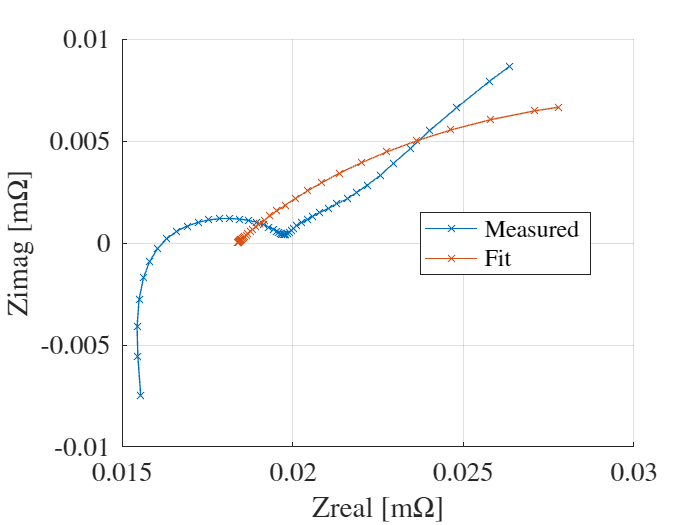


figure
hold all
plot(zr0,-zi0,'x-', DisplayName='Measured')

a = parestimation(fitPar,inputvariablevertcat); %evaluate the circuit model with the fitted parameters
plot(a(1:(length(a)/2)),-a((length(a)/2+1):length(a)),'x-', DisplayName='Fit')
xlabel('Zreal [m$\Omega$]')
ylabel('Zimag [m$\Omega$]')
grid on
legend(location='best')


% Task 1) b.
% Needs to be completed


## IC/DV Analysis

% Task 2) a.
rpt_cyc0 = readtable('RPT_0.csv');

rpt_cyc12000 = readtable('RPT_12000.csv');

rpt_cyc24000 = readtable('RPT_24000.csv');

rpt_cyc0 = rpt_cyc0(2:end,:);

Vol_0 = rpt_cyc0.Voltage(rpt_cyc0.Step==11 & rpt_cyc0.Cycle==0 & rpt_cyc0.CycleLevel==0 & rpt_cyc0.Current > 1.498);
Cap_0 = rpt_cyc0.AhStep(rpt_cyc0.Step==11 & rpt_cyc0.Cycle==0 & rpt_cyc0.CycleLevel==0 & rpt_cyc0.Current > 1.498);

%% Preprocess the measurement data
% Filter the data (voltage, capacity) e.g., by using movmean and sgolayfilt


% Compute IC and DV curves (see slide 11, Lecture 10)


% Plot IC and DV curves


% Task 2) b.
% Needs to be completed

function fitfunction = parestimation(par, inputvariablevertcat)
% This function serves as a definition of your model - electrical circuit
% and formats frequency and impedance in the required way
w = 2*pi*inputvariablevertcat ; %omega, angular frequency

R0 = par(1);
R1 = par(2);
Q1 = par(3);
n1 = par(4);
% complete based on your selected circuit


% here, you need to define impedance equations for your elements (see slide
% 18, Lecture 10). You will need to do impedance series and parallel
% operations

Z0 = R0;

for k = 1:length(w)
    ZCPE1 = 1/(Q1*1i.*w(k)).^n1;                   %Example of CPE impedance
    ZRCPE1(k,1) = (R1 .* ZCPE1) ./ (R1 + ZCPE1);  %Example of R||CPE impedance

    % complete based on your selected circuit
    % It shall be possible to do this with matrix operation. However,
    % it did not worked for me, so I worked around it by for loop. If you
    % will demonstrate matrix operation at exam, that will be points up.


end


Zall = Z0 + ZRCPE1;    %compute total impedance of the circuit... edit based on your topology

firsthalf = Zall(1:(length(Zall)/2));
secondhalf = Zall((length(Zall)/2+1):length(Zall));
fitfunction = vertcat(real(firsthalf),imag(secondhalf)); 
end